% Jep Brinkmann Thesis HMM example
clc; close all;

Initiate the HMM

k = number of states

d = number of possible observational values

T = transition matrix

O = emission matrix

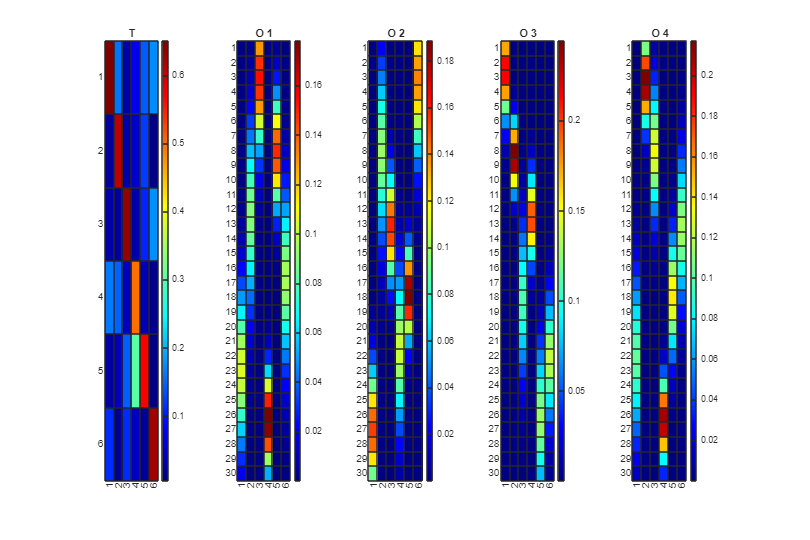

k = 6;
d = 30;
n = 4;

options.method = "random";
options.lambda = 5;

[T, O, pi] = generateHMM(k, d, n, options);


if(n < 5)
    figure('Renderer', 'painters', 'Position', [10 10 900 600])
    
    subplot(1, n+1, 1);
    h = heatmap(T, Colormap=jet());
    h.Title = 'T';
    
    for i = 1:n
        subplot(1, n+1, i+1);
        h = heatmap(O{i}, Colormap=jet());
        h.Title = ['O ' num2str(i)];
    end
end

Generate an observational sequence based on the defined HMM

use_optimal_JPT = false;


T_seq = 1e6;
P3 = zeros(d, d, d, n);

tic
for i = progress(1:n)
    if use_optimal_JPT
        U = {};
        U{1} = (O{i} * diag(pi) * T' / inv(diag(T * pi')));
        U{2} = O{i};
        U{3} = (O{i} * T);
        P3(:, :, :, i) = cpdgen(U)/k;
    else
        Taug = [0, pi; zeros(k, 1), T'];
        Oaug = [zeros(1, d); O{i}'];
        [tempSeq, ~] = hmmgenerate(T_seq, Taug, Oaug);
        P3(:, :, :, i) = ProbabilityTensorGenerate(tempSeq, 3, d);
    end
end

Processing:  000%  |                                          | 0/4it [00:00:00<Inf:NaN:NaN, Inf it/s]


toc

Elapsed time is 18.693842 seconds.


## Run seperate CPDs


O_hat = zeros(size(O));
T_hats = zeros(k, k, n);
T_hat = zeros(size(T));

permErros = zeros(1, n);
totalError = zeros(1, n);

Os = {};

tic
for i = progress(1:n)
    U = cpd(P3(:, :, :, i), k);

    O_hat(:, :, i) = U{2};
    T_hats(:, :, i) = Stochasticize(pinv(Stochasticize(U{2})) * Stochasticize(U{3}));

    Pbest = PermutationFit(T, T_hats(:, :, i));
    T_hat = T_hat + (1/n) * (Pbest * T_hats(:, :, i) * Pbest');
    O_hat(:, :, i) = Stochasticize(O_hat(:, :, i) * Pbest');

    permErros(i) = norm(T-Pbest * T_hats(:, :, i) * Pbest', "fro");
    totalError(i) = norm(T-T_hat, "fro");
end

Processing:  000%  |                                          | 0/4it [00:00:00<Inf:NaN:NaN, Inf it/s]


Unable to perform assignment because the size of the left side is 4-by-1 and the size of the right side is 30-by-6.

toc

figure()
plot(1:n, permErros)
if(n < 5)
    figure('Renderer', 'painters', 'Position', [10 10 900 600])

    subplot(1, n+1, 1);
    h = heatmap(T_hat, Colormap=jet());
    h.Title = 'T_{hat}';
    
    for i = 1:n
        subplot(1, n+1, i+1);
        h = heatmap(O_hat(:, :, i), Colormap=jet());
        h.Title = ['O_{hat} ' num2str(i)];
    end
end




 
J = norm(T-T_hat, "fro")

figure('Renderer', 'painters', 'Position', [10 10 1200 600])

subplot(1, 3, 1);
h = heatmap(T, Colormap=jet());
h.Title = 'T';

subplot(1, 3, 2);
h = heatmap(T_hat, Colormap=jet());
h.Title = 'T_{hat}';

subplot(1, 3, 3);
h = heatmap(abs(T-T_hat), Colormap=jet());
h.Title = 'T_{error}';
